clc;
clear;

% Load training data and labels
train_data_x = load('data_train.mat');
train_data_y = load('data_train_labels.mat');
train_data_x = train_data_x.data_train;
train_data_y = train_data_y.data_train_labels;

% Define label names
label_names = {'normal', 'roller', 'inner', 'outer', ...
               'inner+roller', 'outer+inner', 'outer+inner+roller', 'outer+roller'};

% Use 'data_train_labels' as your target labels
target_labels = train_data_y';

% Define parameters for your dataset (adjust these based on your specifications)
theta = 14.94 * pi / 180; % Convert contact angle from degrees to radians
n = 17;
d = 0.01; % in meters
D = 0.06; % in meters
fi = 800 / 60; % Convert rpm to Hz

% Preallocate feature matrix
num_columns = numel(train_data_x);
num_features = 5; % Including skewness_value, std_deviation,mav_value,spectral_centroid_bin,kurtosis_value
time_domain_features = zeros(num_columns, num_features);

% Compute and populate the time domain feature matrix
for col = 1:num_columns
    data = train_data_x{col};
    %mean_value = mean(data);
    std_deviation = std(data);
    rms_value = rms(data);
    mav_value = mean(abs(data));
    skewness_value = skewness(data);
    kurtosis_value = kurtosis(data);
    fft_data = fft(data);
    N = length(data);
    fft_normalized = abs(fft_data/N);
    % first_order_harmonic = fft_normalized(2);
    % second_order_harmonic = fft_normalized(3);
    crest_factor = max(data) / rms_value;
    impulse_factor = max(data) / mean(abs(data));
    % clearance_factor = max(data) / (max(data) - min(data));
    p2p=max(data)-min(data);
    bin_indices = (0:N-1)';
    spectral_centroid_bin = sum(bin_indices .* fft_normalized) / sum(fft_normalized);
    shape_factor = rms_value / mav_value;
    zero_crossings = sum(abs(diff(data > 0))) / length(data);
    waveform_length = sum(abs(diff(data)));
    slope_changes = diff(data);
    ssc_count = sum((slope_changes(1:end-1) .* slope_changes(2:end)) < -theta);
    time_domain_features(col, :) = [skewness_value, std_deviation,mav_value,spectral_centroid_bin,kurtosis_value];
end

% Perform k-fold cross-validation
k = 5; % Number of folds
cv = cvpartition(numel(target_labels), 'KFold', k);

% Display the partitioning of k-fold and the number of data in each fold
disp('Partitioning of K-Fold Cross-Validation:');

Partitioning of K-Fold Cross-Validation:


for i = 1:k
    train_idx = training(cv, i);
    val_idx = test(cv, i);
    disp(['Fold ', num2str(i), ': Training Set - ', num2str(sum(train_idx)), ' samples, Validation Set - ', num2str(sum(val_idx)), ' samples']);
end

Fold 1: Training Set - 1639 samples, Validation Set - 409 samples
Fold 2: Training Set - 1638 samples, Validation Set - 410 samples
Fold 3: Training Set - 1638 samples, Validation Set - 410 samples
Fold 4: Training Set - 1638 samples, Validation Set - 410 samples
Fold 5: Training Set - 1639 samples, Validation Set - 409 samples



% Initialize variables to store evaluation metrics
accuracy = zeros(k, 1);
conf_matrices = cell(k, 1);

for i = 1:k
    % Training set
    train_idx = training(cv, i);
    train_features = time_domain_features(train_idx, :);
    train_labels = target_labels(train_idx);
    
    % Validation set
    val_idx = test(cv, i);
    val_features = time_domain_features(val_idx, :);
    val_labels = target_labels(val_idx);
    
    % Train KNN model
    knn_model = fitcknn(train_features, label_names(train_labels), 'NumNeighbors', 3);
    
    % Predict labels for validation set
    predicted_labels_knn = predict(knn_model, val_features)';
    
    % Evaluate performance
    conf_matrices_knn{i} = confusionmat(label_names(val_labels), predicted_labels_knn, 'Order', label_names);
    accuracy_knn(i) = sum(strcmp(predicted_labels_knn, label_names(val_labels))) / numel(val_labels);
    for j = 1:numel(label_names)
        TP = conf_matrices_knn{i}(j, j);
        FP = sum(conf_matrices_knn{i}(:, j)) - TP;
        FN = sum(conf_matrices_knn{i}(j, :)) - TP;
        TN = sum(conf_matrices_knn{i}(:)) - TP - FP - FN;

        precision_knn(i, j) = TP / (TP + FP);
        recall_knn(i, j) = TP / (TP + FN);
        f1Scores_knn(i, j) = 2 * ((precision_knn(i, j) * recall_knn(i, j)) / (precision_knn(i, j) + recall_knn(i, j)));
    end
end


% Calculate average performance metrics for Support Vector Machine (SVM)
avg_accuracy_knn = mean(accuracy_knn);
avg_precision_knn = mean(precision_knn, 1);
avg_recall_knn = mean(recall_knn, 1);
avg_f1Scores_knn = mean(f1Scores_knn, 1);


% Display k-fold cross-validation results for Support Vector Machine (SVM)
disp("K-Nearest NEighbor (KNN) Results:");

K-Nearest NEighbor (KNN) Results:


disp(['Average Accuracy: ', num2str(avg_accuracy_knn * 100), '%']);

Average Accuracy: 99.2187%


disp('Average Precision:');

Average Precision:


disp(avg_precision_knn);

    1.0000    1.0000    0.9923    0.9904    0.9739    0.9773    1.0000    1.0000



disp('Average Recall:');

Average Recall:


disp(avg_recall_knn);

    0.9923    0.9902    1.0000    1.0000    0.9784    0.9750    1.0000    1.0000



disp('Average F1-Score:');

Average F1-Score:


disp(avg_f1Scores_knn);

    0.9961    0.9951    0.9961    0.9951    0.9758    0.9758    1.0000    1.0000




% Display k-fold cross-validation results for Random Forest
disp("For KNN, Number of Nearest Neighbors (k): 3, Number of Features: 5 ")

For KNN, Number of Nearest Neighbors (k): 3, Number of Features: 5 


disp(['Average Accuracy: ', num2str(avg_accuracy_knn * 100), '%']);

Average Accuracy: 99.2187%


disp('Confusion Matrices:');

Confusion Matrices:


Fold 1


    63     0     0     0     0     0     0     0
     0    53     0     0     0     0     0     0
     0     0    48     0     0     0     0     0
     0     0     0    53     0     0     0     0
     0     0     0     0    49     1     0     0
     0     0     0     0     1    60     0     0
     0     0     0     0     0     0    51     0
     0     0     0     0     0     0     0    30



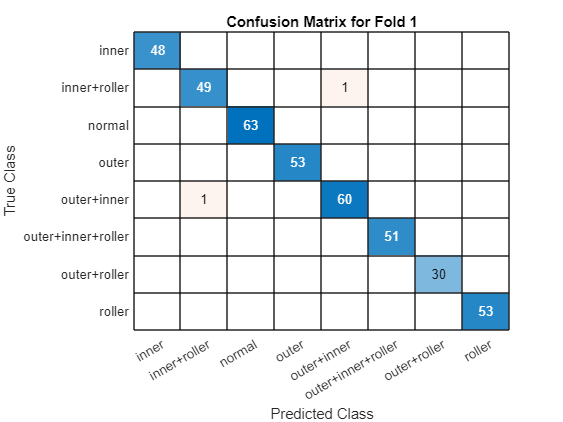

Fold 2


    55     0     1     0     0     0     0     0
     0    31     0     1     0     0     0     0
     0     0    59     0     0     0     0     0
     0     0     0    40     0     0     0     0
     0     0     0     0    57     1     0     0
     0     0     0     0     0    52     0     0
     0     0     0     0     0     0    56     0
     0     0     0     0     0     0     0    57



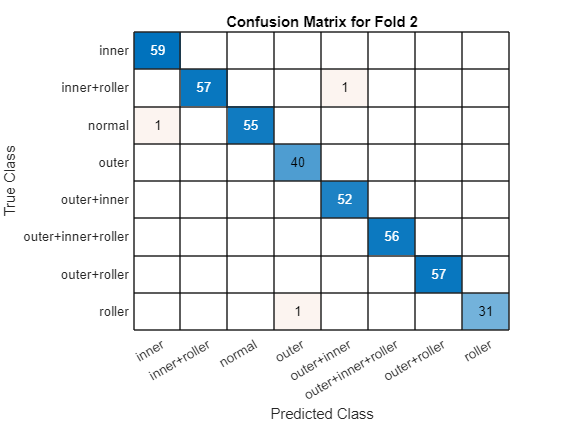

Fold 3


    43     0     0     0     0     0     0     0
     0    58     0     0     0     0     0     0
     0     0    56     0     0     0     0     0
     0     0     0    65     0     0     0     0
     0     0     0     0    41     0     0     0
     0     0     0     0     2    44     0     0
     0     0     0     0     0     0    49     0
     0     0     0     0     0     0     0    52



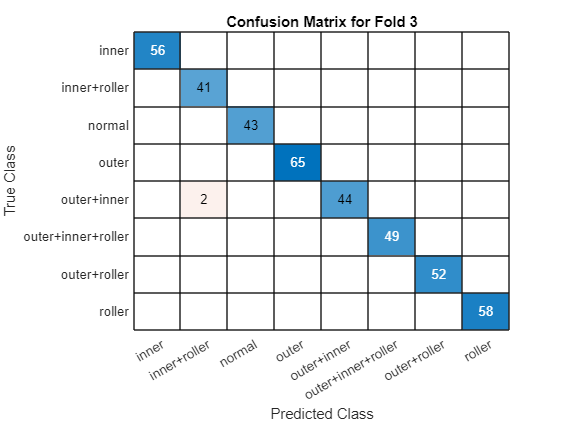

Fold 4


    46     0     0     0     0     0     0     0
     0    56     0     1     0     0     0     0
     0     0    48     0     0     0     0     0
     0     0     0    41     0     0     0     0
     0     0     0     0    59     3     0     0
     0     0     0     0     0    51     0     0
     0     0     0     0     0     0    52     0
     0     0     0     0     0     0     0    53



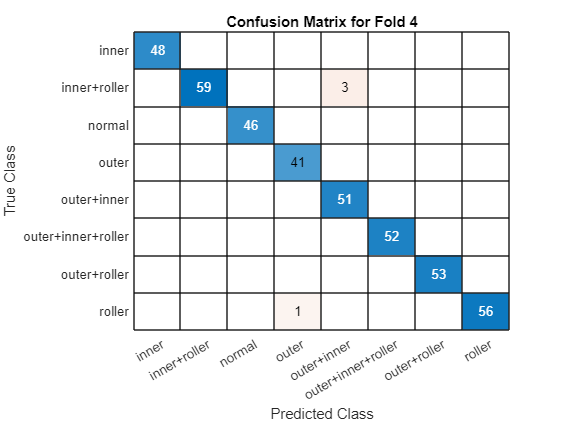

Fold 5


    47     0     1     0     0     0     0     0
     0    56     0     0     0     0     0     0
     0     0    45     0     0     0     0     0
     0     0     0    57     0     0     0     0
     0     0     0     0    44     1     0     0
     0     0     0     0     3    43     0     0
     0     0     0     0     0     0    48     0
     0     0     0     0     0     0     0    64



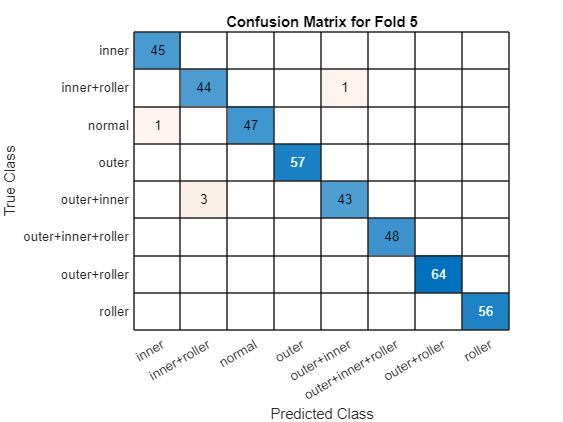

for i = 1:k
    disp(['Fold ', num2str(i)]);
    disp(conf_matrices_knn{i});
    
    % Create confusion matrix plot
    figure;
    confusionchart(conf_matrices_knn{i}, label_names);
    title(['Confusion Matrix for Fold ', num2str(i)]);
end